2. PCA

a.

x1 = [1.1340 3.0981];
x2 = [2.8660 2.0981];
x3 = [1.8660 -2.0981];
x4 = [-0.1340 -3.0981];
Q = zeros(2);
for i = 1:2
    for j = 1:2
Q(i,j) = 1/4*(x1(i)*x1(j)+x2(i)*x2(j)+x3(i)*x3(j)+x4(i)*x4(j));
    end
end
mu(1) = (x1(1)+x2(1)+x3(1)+x4(1));
mu(2) = (x1(2)+x2(2)+x3(2)+x4(2));
C = zeros(2);
for i = 1:2
    for j = 1:2
C(i,j) = 1/4*(x1(i)*x1(j)+x2(i)*x2(j)+x3(i)*x3(j)+x4(i)*x4(j))-mu(i)*mu(j);
    end
end
[V1,D1] = eig(Q);
[V2,D2] = eig(C);

The correlation matrix and covariance matrix of given inputs are $\left\lbrack \begin{array}{c}
3\ldotp 2500 & 1\ldotp 5066\\
1\ldotp 5066 & 7\ldotp 0001
\end{array}\right\rbrack$and $\left\lbrack \begin{array}{c}
-29\ldotp 6059 & 1\ldotp 5066\\
1\ldotp 5066 & 7\ldotp 0001
\end{array}\right\rbrack$respectively.

The eigen values and vectors of correlation matrix are $\lambda_1 = 2.7197, z_1 = (-0.9433, 0.3302)^T\\
\lambda_2 = 7.5304, z_2 = (0.3302, 0.9433)^T
$; and those of covariance matrix are $\lambda_1 = -29.6678, z_1 = (-0.9992, 0.0411)^T\\
\lambda_2 = 7.5304, z_2 = (-0.0411, -0.9992)^T
$.

b. when stimulation using the Oja rule, the weight factor converge to the eigen vector of correlation matrix with highest eigen value, where $|w^2| = 1$.

c.

eta = 0.5;
n =400;
w = zeros(2,n);
w(:,1) = [0.05, 0.05];
dt = 0.01;
T = n*dt;
for k = 1:n
    dw = eta*(Q*w(:,k)-(w(:,k)'*Q*w(:,k))*w(:,k));
    w(:,k+1)=w(:,k)+dw*dt;
end

Given initial weight factor $w = (0.05, 0.05)
$, the weight factor eventually converge to $w = (0.3320, 0.9433)$, which is same as analytical solution.

3. Receptor model

a. the kinetic equations for C and O are :$\frac{d[C]}{dt} = -k_1[C]+(k_0+T\cdot k_{-1})[O]\\
\frac{d[O]}{dt} = k_1[C]-(k_0+T\cdot k_{-1})[O]$.

At steady states, $T=0$,  $\frac{d[C]}{dt} = 0,  [C] = \frac{k_0}{k_1}[O],  [O] = \frac{k_1}{k_0+k_1}$ .

b. for t < 1, 


$$\frac{d[C]}{dt} = -k_1[C]+(k_0+k_{-1})[O] =-k_1[C]+(k_0+k_{-1})(1-[C]) = (k_0+k_{-1}+k_1)(1-[C])$$



$$[C] = 1-e^{-(k_1+k_0+k_{-1})t}+[C]_0 = 1-e^{-(k_1+k_0+k_{-1})t}+\frac{k_0}{k_0+k_1}$$



$$[C]_1 = 1-e^{-(k_1+k_0+k_{-1})t}+\frac{k_0}{k_0+k_1}$$


for t > 1 


$$\frac{d[C]}{dt} = -k_1[C]+k_0[O] =-k_1[C]+k_0(1-[C]) = (k_0+k_1)(\frac{k_0}{k_0+k_1}-[C])$$



$$[C] = e^{-(k_0+k_1)}-e^{-(k_0+k_1)t}+[C]_1=e^{-(k_0+k_1)}-e^{-(k_0+k_1)t}+1-e^{k_1-k_0-k_{-1}}+\frac{k_0}{k_0+k_1}$$



$$[O] = 1- [C]=+e^{-(k_0+k_1)t}-e^{-(k_0+k_1)}+e^{-(k_1+k_0+k_{-1})}-\frac{k_0}{k_0+k_1}$$



$$\tau = \frac{1}{k_0+k_1}$$



$$\lim_{t->\infty}[C] = e^{-(k_0+k_1)}-e^{-k_1-k_0-k_{-1}}+\frac{k_0}{k_0+k_1}\\
\lim_{t->\infty}[O] = -e^{-(k_0+k_1)}+e^{-k_1-k_0-k_{-1}}+\frac{k_1}{k_0+k_1}$$


c. 

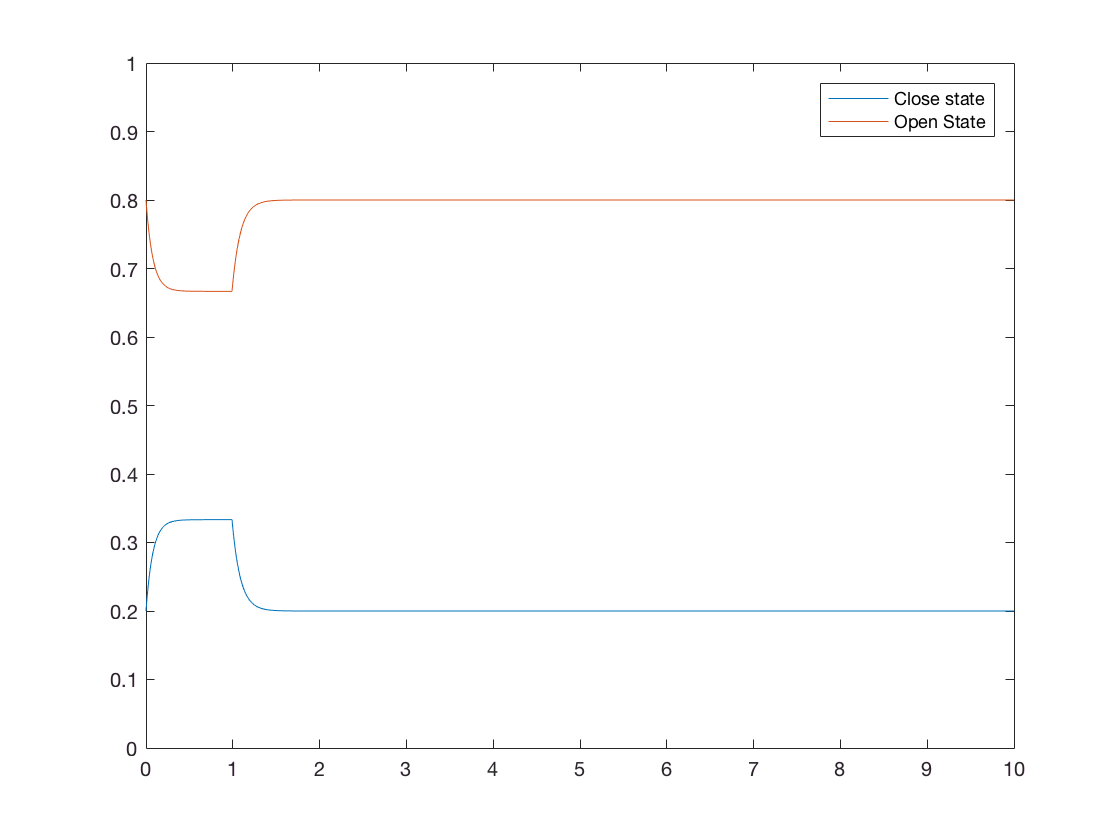

figure(1)
dt = 0.01;
kr1 = 2;
k0 = 2;
k1 = 8;
T1 = 1;
T2 = 10;
N = T1/dt;
n = T2/dt;
C = zeros(1,n);
O = C;
C(1) = k0/(k1+k0);
O(1) = k1/(k1+k0);
for i = 2:N
    dC = k0+kr1-(k1+k0+kr1)*C(i-1);
    C(i)=C(i-1)+dC*dt;
end
for i = N+1:n
    dC = k0-(k0+k1)*C(i-1);
    C(i)= C(i-1)+dC*dt;
end
O = ones(1,n)-C;
t = linspace(0,T2,n);
plot(t,C,t,O)
legend('Close state','Open State')
ylim([0,1])

4. BCM

a. 

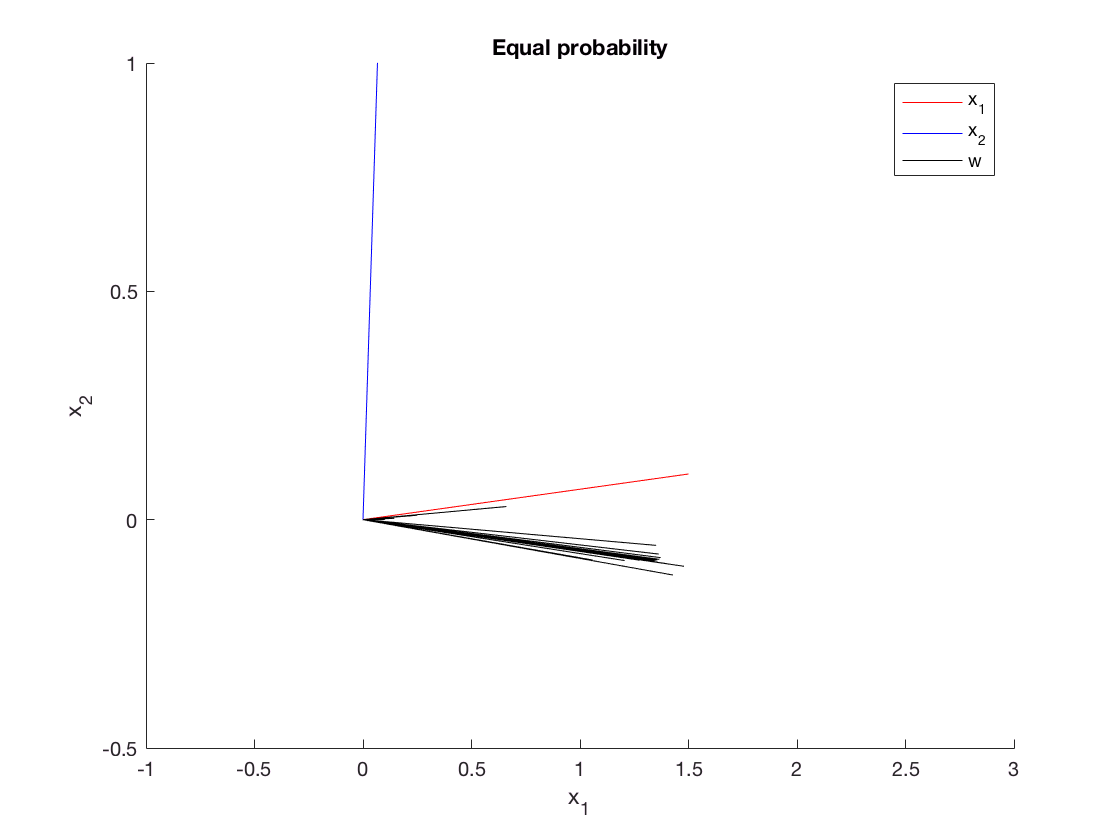

figure(2)
X = [1.5 0.1;0.1 1.5];
w0 = [0.1;0];
p = [1/2 1/2];
tau = 5;
eta = 0.1;
y = w0'*X;
theta = p*y'.^2;
w = w0;
plot([0 X(1,1)],[0 X(2,1)],'-r')
hold on 
plot([0 X(1,2)],[0 X(2,2)],'-b')
plot([0 w(1)],[0 w(2)],'k')
xlabel('x_1')
xlim([-1 3])
ylabel('x_2')
ylim([-0.5 1])
for i = 1:500
    dtheta = 1/tau*(p*y'.^2-theta);
    theta = dtheta+theta;
    dw = eta*X(:,1)*p(1)*y(1)*(y(1)-theta)+eta*X(:,2)*p(2)*y(2)*(y(2)-theta);
    w = dw+w;
    y = w'*X;
    if (mod(i,20) == 0)
    plot([0 w(1)],[0 w(2)],'k')
    end
end
hold off
box off
legend('x_1','x_2','w')
title('Equal probability')

y = zeros(2,4);
w1 = y;
theta1 = zeros(1,4);
y(:,1) = [0;0];
y(:,2) = [1/p(1);0];
y(:,3) = [0;1/p(2)];
y(:,4) = [1/(p(1)+p(2));1/(p(1)+p(2))];
for i = 1:4
    w1(:,i) = X\y(:,i);
    theta1(i) = p(1)*y(1,i)^2+p(2)*y(2,i)^2;
end

There are 4 fixed points: two stable fixed points $\left(2,0\right)\text{ }\mathrm{and}\text{ }\left(0,2\right)$, and two unstable fixed points $\left(0,0\right)\text{ }\mathrm{and}\text{ }\left(1,1\right)\ldotp$

with $w$ and $\theta$: $\left(1\ldotp 3393,-0\ldotp 0893\right)$, 2; $\left(-\mathrm{0 . 0893},\text{ }1\ldotp 3393\right)$, 2; $\left(0,0\right)$, 0; and $\left(0\ldotp 6250,0\ldotp 6250\right)$, 1 respectively.

b.

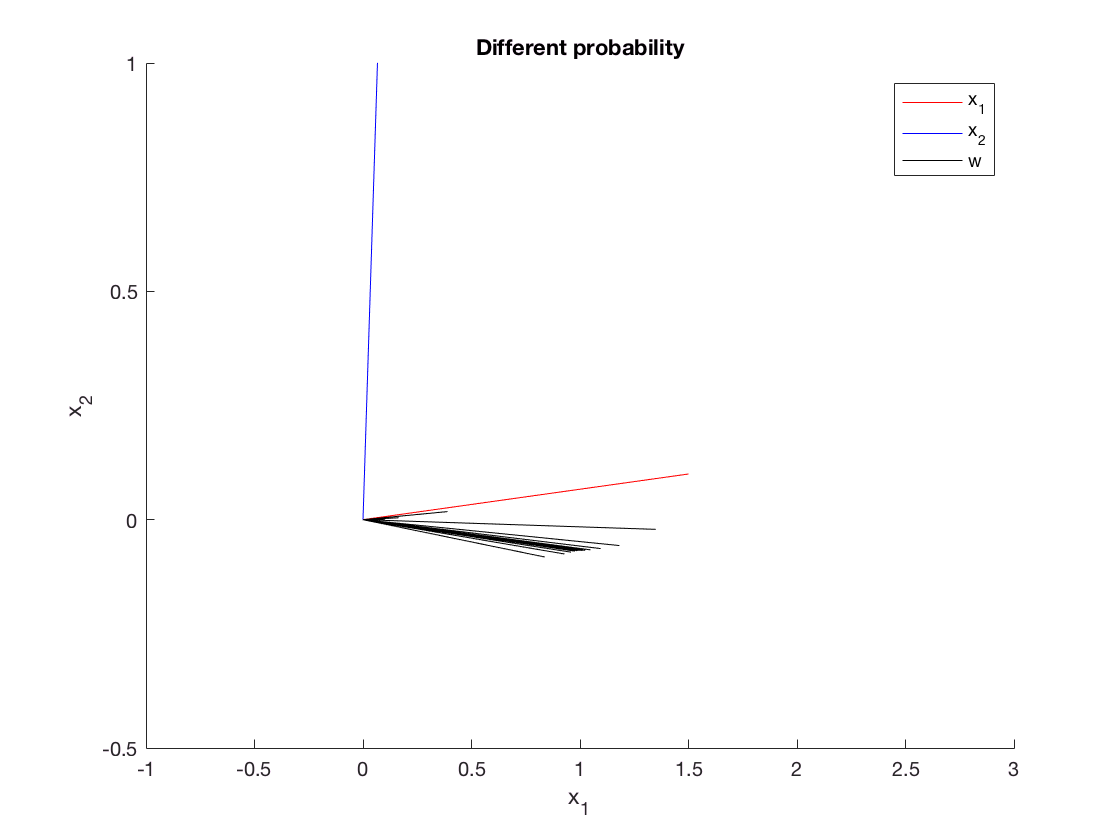

figure(3)
X = [1.5 0.1;0.1 1.5];
w0 = [0.1;0];
p = [2/3 1/3];
tau = 5;
eta = 0.1;
y = w0'*X;
theta = p*y'.^2;
w = w0;
plot([0 X(1,1)],[0 X(2,1)],'-r')
hold on 
plot([0 X(1,2)],[0 X(2,2)],'-b')
plot([0 w(1)],[0 w(2)],'k')
xlabel('x_1')
xlim([-1 3])
ylabel('x_2')
ylim([-0.5 1])
for i = 1:500
    dtheta = 1/tau*(p*y'.^2-theta);
    theta = dtheta+theta;
    dw = eta*X(:,1)*p(1)*y(1)*(y(1)-theta)+eta*X(:,2)*p(2)*y(2)*(y(2)-theta);
    w = dw+w;
    y = w'*X;
    if (mod(i,20) == 0)
    plot([0 w(1)],[0 w(2)],'k')
    end
end
hold off
box off
legend('x_1','x_2','w')
title('Different probability')

y = zeros(2,4);
w1 = y;
theta1 = zeros(1,4);
y(:,1) = [0;0];
y(:,2) = [1/p(1);0];
y(:,3) = [0;1/p(2)];
y(:,4) = [1/(p(1)+p(2));1/(p(1)+p(2))];
for i = 1:4
    w1(:,i) = X\y(:,i);
    theta1(i) = p(1)*y(1,i)^2+p(2)*y(2,i)^2;
end

There are 4 fixed points: two stable fixed points $\left(1\ldotp 5,0\right)\text{ }\text{and}\text{ }\left(0,3\right)$, and two unstable fixed points $\left(0,0\right)\text{ }\text{and}\text{ }\left(1,1\right)\ldotp$

with $w$ and $\theta$: $\left(1\ldotp 0045,-0\ldotp 0670\right)$, 1.5; $\left(-\text{0 .}1339,2\ldotp 0089\right)$, 3; $\left(0,0\right)$, 0; and $\left(0\ldotp 6250,0\ldotp 6250\right)$, 1;

c. 

theta1 = 0;
eta = 0.1;
y1 = 0.05;
dt = 0.01;
T = 1000;
N = T/dt;
for i = 1:N
    dtheta = y1^1.5-theta1;
    theta1 = theta1+dtheta*dt;
    dy = eta*y1*(y1-theta1);
    y1 = y1+dy*dt;
end

there are two fix point, $y = 0$ and $y = \theta_m$

using numerical estimate, the stable fix point is $$y = 1, \theta_m = 1$
$(given $$\rho = 0.5$$) .

5. Reinforcement learning

with $\gamma = 1$

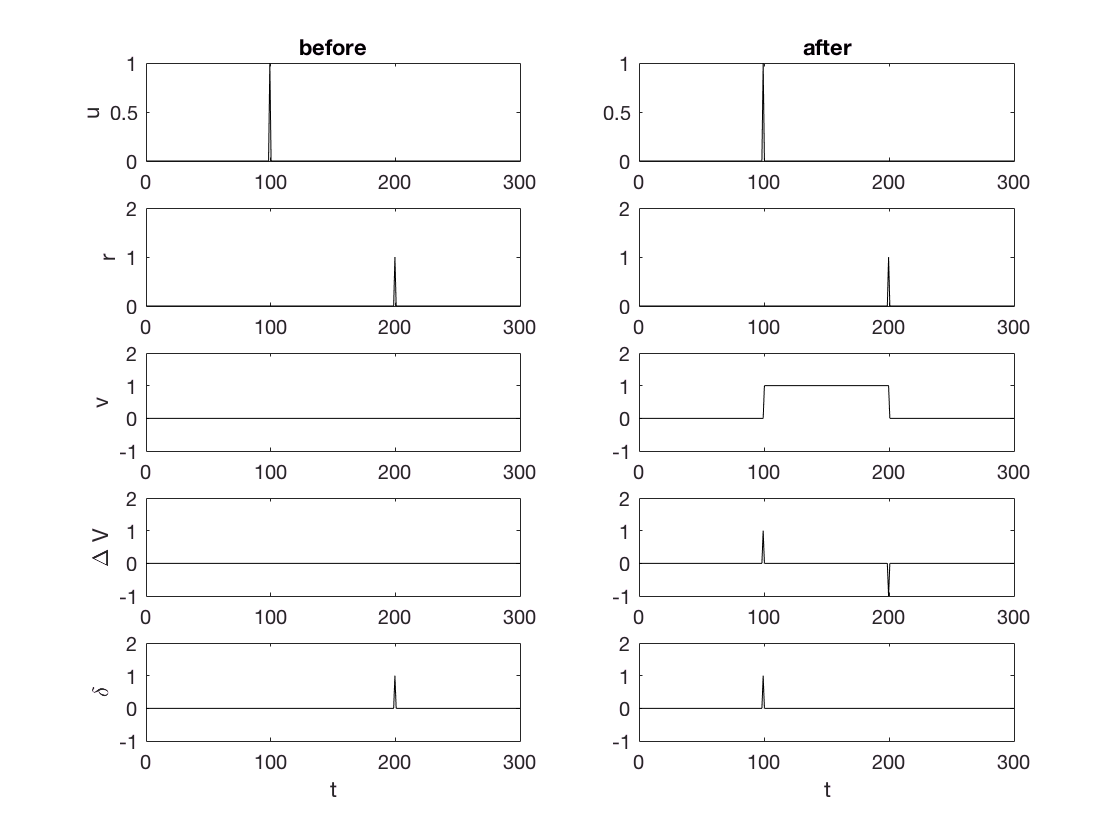

figure(4)
u = zeros(1,300);
u(100) = 1;
r = zeros(1,300);
r(200) = 1;
v = zeros(1,300);
w = v;
d = v;
dv = v;
v1 =v;
d1 = d;
dj = zeros(500,300);
t = linspace(0,300,300);
gamma = 1;
for j = 1:500
for i = 1:299
    v(i+1)=v(i+1)+sum(d(i+1)*u(1:i));
    d(i)=r(i)+gamma*(v(i+1)-v(i));
end
if j == 1
    v1 = v;
    d1 = d;
end
dj(j,:)=d;
end
subplot(5,2,1)
plot(t,u,'k')
xlim([0 300])
ylim([0 1])
subplot(5,2,3)
plot(t,r,'k')
xlim([0 300])
ylim([0 2])
subplot(5,2,5)
plot(t,v1,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,7)
for s = 1:299
    dv(s) = v1(s+1)-v1(s);
end
plot(t,dv,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,9)
plot(t,d1,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,2)
plot(t,u,'k')
xlim([0 300])
ylim([0 1])
subplot(5,2,4)
plot(t,r,'k')
xlim([0 300])
ylim([0 2])
subplot(5,2,6)
plot(t,v,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,8)
for s = 1:299
    dv(s) = v(s+1)-v(s);
end
plot(t,dv,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,10)
plot(t,d,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,1)
title('before')
ylabel('u')
subplot(5,2,2)
title('after')
subplot(5,2,3)
ylabel('r')
subplot(5,2,5)
ylabel('v')
subplot(5,2,7)
ylabel('\Delta V')
subplot(5,2,9)
xlabel('t')
ylabel('\delta')
subplot(5,2,10)
xlabel('t')

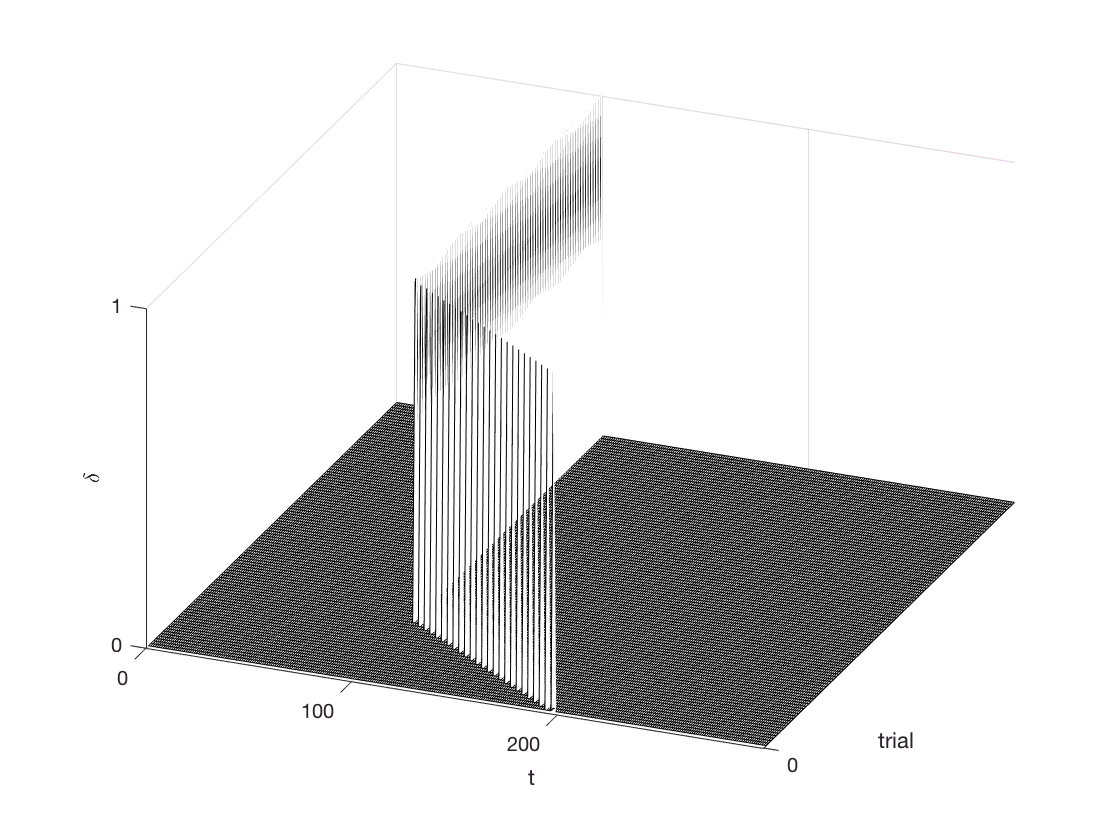

figure(5)
for j = 1:400
    if mod(j,4)==0
       djj(j/4,:) = dj(j,:);
    end
end
j =1:1:100;
h = axes;
mesh(j,t,djj')
set(h,'Ydir','reverse')
colormap gray
xticks([0])
xlabel('trial')
yticks([0 100 200])
ylabel('t')
zticks([0 1 2])
zlabel('\delta')
view([-67.901 37.991])

given a different $\gamma = 0.5$

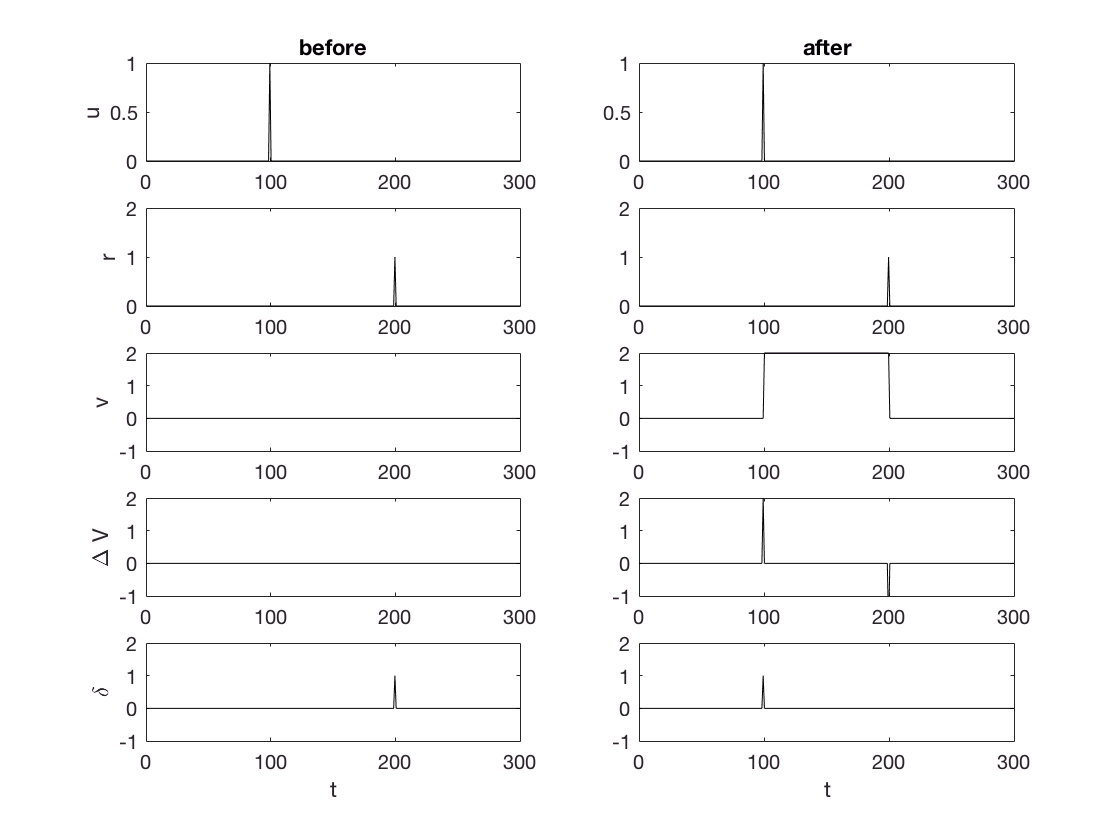

figure(6)
u = zeros(1,300);
u(100) = 1;
r = zeros(1,300);
r(200) = 1;
v = zeros(1,300);
w = v;
d = v;
dv = v;
v1 =v;
d1 = d;
dj = zeros(500,300);
t = linspace(0,300,300);
gamma = 0.5;
for j = 1:500
for i = 1:299
    v(i+1)=v(i+1)+sum(d(i+1)*u(1:i));
    d(i)=r(i)+gamma*(v(i+1)-v(i));
end
if j == 1
    v1 = v;
    d1 = d;
end
dj(j,:)=d;
end
subplot(5,2,1)
plot(t,u,'k')
xlim([0 300])
ylim([0 1])
subplot(5,2,3)
plot(t,r,'k')
xlim([0 300])
ylim([0 2])
subplot(5,2,5)
plot(t,v1,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,7)
for s = 1:299
    dv(s) = v1(s+1)-v1(s);
end
plot(t,dv,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,9)
plot(t,d1,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,2)
plot(t,u,'k')
xlim([0 300])
ylim([0 1])
subplot(5,2,4)
plot(t,r,'k')
xlim([0 300])
ylim([0 2])
subplot(5,2,6)
plot(t,v,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,8)
for s = 1:299
    dv(s) = v(s+1)-v(s);
end
plot(t,dv,'k')
xlim([0 300])
ylim([-1 2])
subplot(5,2,10)
plot(t,d,'k')
xlim([0 300])
ylim([-1 2])

subplot(5,2,1)
title('before')
ylabel('u')
subplot(5,2,2)
title('after')
subplot(5,2,3)
ylabel('r')
subplot(5,2,5)
ylabel('v')
subplot(5,2,7)
ylabel('\Delta V')
subplot(5,2,9)
xlabel('t')
ylabel('\delta')
subplot(5,2,10)
xlabel('t')

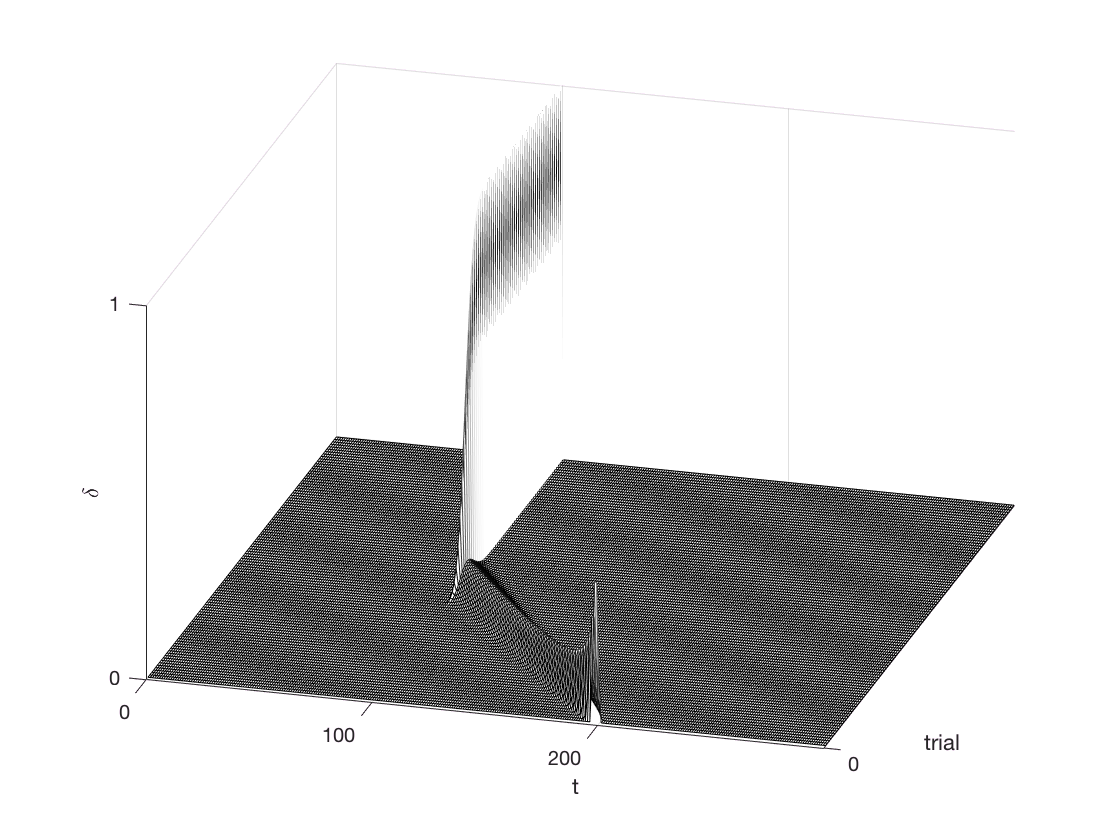

figure(7)
for j = 1:400
    if mod(j,4)==0
       djj(j/4,:) = dj(j,:);
    end
end
j =1:1:100;
h = axes;
mesh(j,t,djj')
set(h,'Ydir','reverse')
colormap gray
xticks([0])
xlabel('trial')
yticks([0 100 200])
ylabel('t')
zlim([0 1])
zticks([0 1])
zlabel('\delta')
view([-74.301 33.996])